# Tutorial March 26

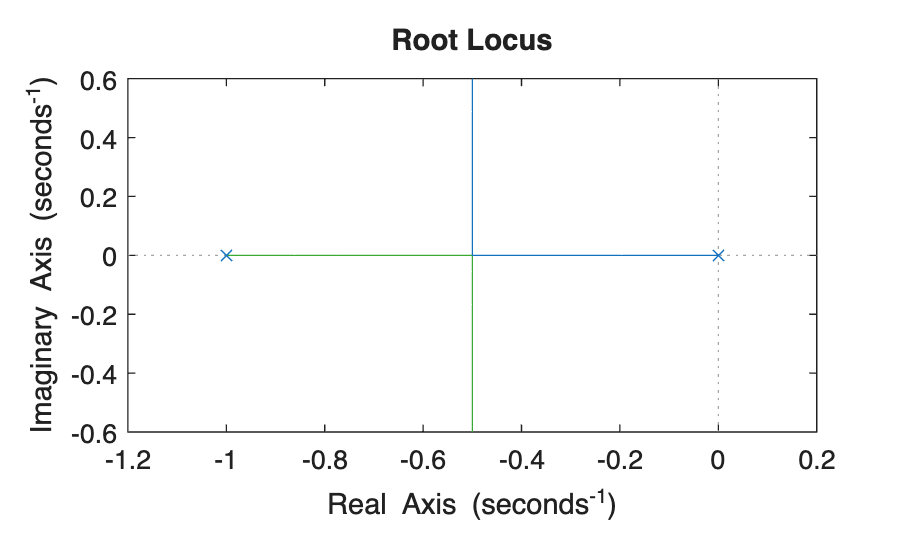

clearvars , close all, clc

G = tf(1,[1 1 0]);
figure(1)
rlocus(G)


Dc1 = tf(2*[1 2],1)


Dc1 =
 
  2 s + 4
 
Continuous-time transfer function.


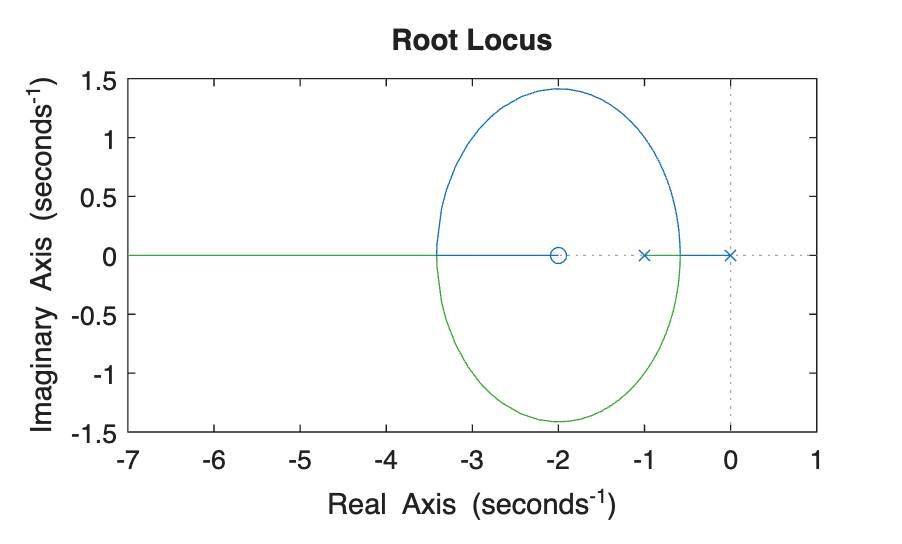

figure(2)
rlocus(Dc1*G)


Dc2 = tf([1,2],[1,20])


Dc2 =
 
  s + 2
  ------
  s + 20
 
Continuous-time transfer function.


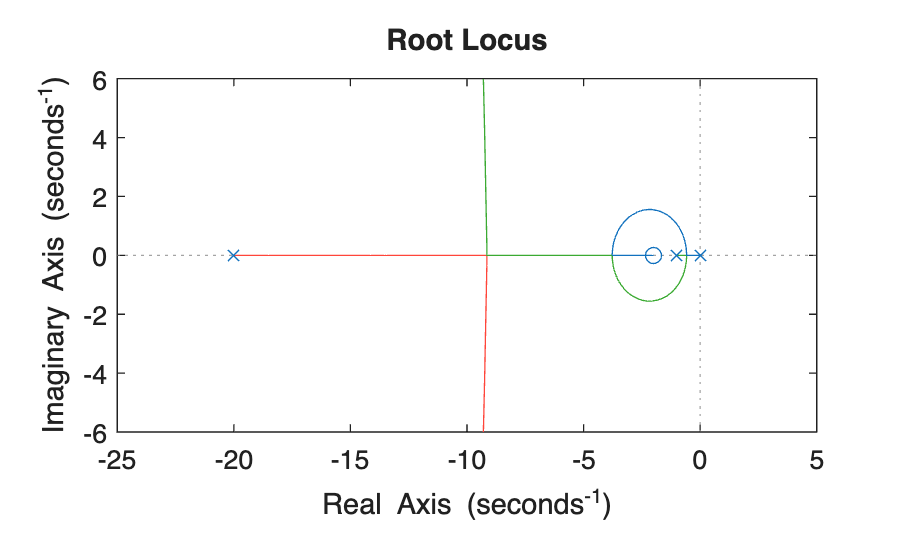

figure(3)
rlocus(Dc2 * G)


Dc3 = tf([1 2],[1 0])


Dc3 =
 
  s + 2
  -----
    s
 
Continuous-time transfer function.


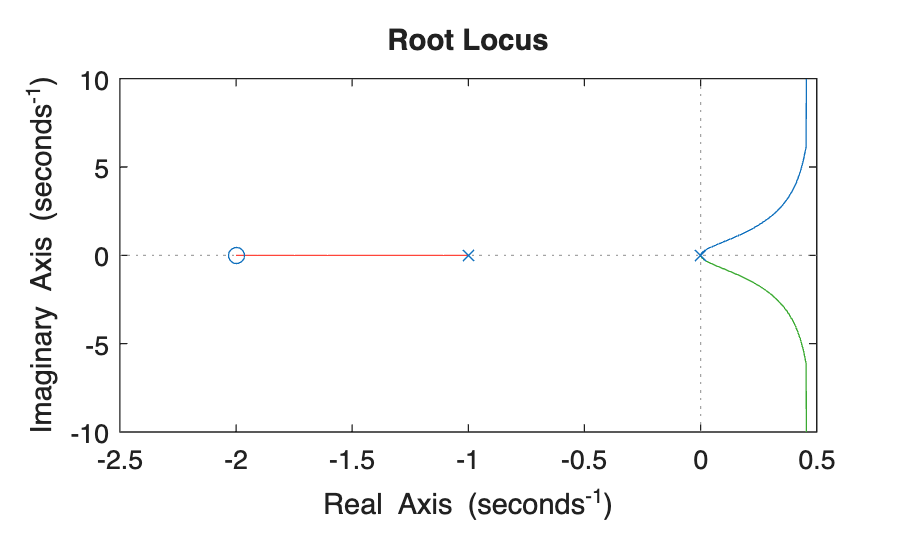

figure(4)
rlocus(Dc3 * G)

axis([-6, 2, -3, 3])

Unable to resolve the name 'controllib.chart.internal.mixin.chart.ConvenienceFunctionMixin.validateAxisValue'.

Error in controllib.chart.internal.foundation.AbstractPlot/axis (line 1510)
                axisArg = controllib.chart.internal.mixin.chart.ConvenienceFunctionMixin.validateAxisValue(axisArgs{ii},true);
                ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^
Error in 


[K,polesCL] = rlocfind(Dc3*G)

T = feedback(K*Dc3*G, 1)

figure(5)
step(T)